Import the data from files:

cubic_data = readmatrix("cubic.csv");
linear_data = readmatrix("linear.csv");
quad_data = readmatrix("quadratic.csv");
nquad_data = readmatrix("noisy_quadratic.csv");
chi_data = readmatrix("chi2fit.csv");

Save data being analysed in a separate array so it's easier to access

dataarr = cubic_data;

Perform the least squares fit and extract parameters:

[a, b, r] = least_squares(dataarr(:, 1), dataarr(:, 2))

a = 1.6500

b = 12.0157

r = 19.2466

Plot:

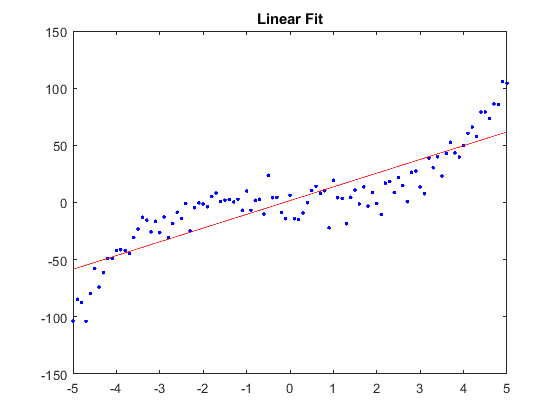

xvals = dataarr(:, 1);
yvals = dataarr(:, 2);
plot(xvals, yvals, ".b") %plot the raw data
hold on
%use the fit parameters to get the fit curve
xfit = linspace(min(xvals), max(xvals), 1000); %1000 x values in range of data points
yfit = (a+b*xfit).';
plot(xfit, yfit, "r-")
title("Linear Fit")
hold off